# **MACHINE LEARNING: PERCEPTRON AND LINEAR REGRESSION**

#### **LINEAR REGRESSION**   

#### Submitted by: Jonabel Eleanor B. Baldres

#### App Physics 157 WFY FX 2

### Training

%Reading the ripe images of mango
cd('~/Documents/MATLAB/mangoripeness/Train/ripe/');
fileList_ripe = dir('*.jpg'); 
numImages_ripe = numel(fileList_ripe);
ripe_images = cell(numImages_ripe, 1);

for i = 1:numImages_ripe
    ripe_images{i} = imread(fileList_ripe(i).name);
end

%Reading the unripe images of mango
cd('~/Documents/MATLAB/mangoripeness/Train/unripe/');
fileList_unripe = dir('*.jpg'); 
numImages_unripe = numel(fileList_unripe);
unripe_images = cell(numImages_unripe, 1);

for i = 1:numImages_unripe
    unripe_images{i} = imread(fileList_unripe(i).name);
end

COLORS = zeros(numImages_ripe+numImages_unripe,4); %array of mean RGB colors
COLORS(:,1) = 1;

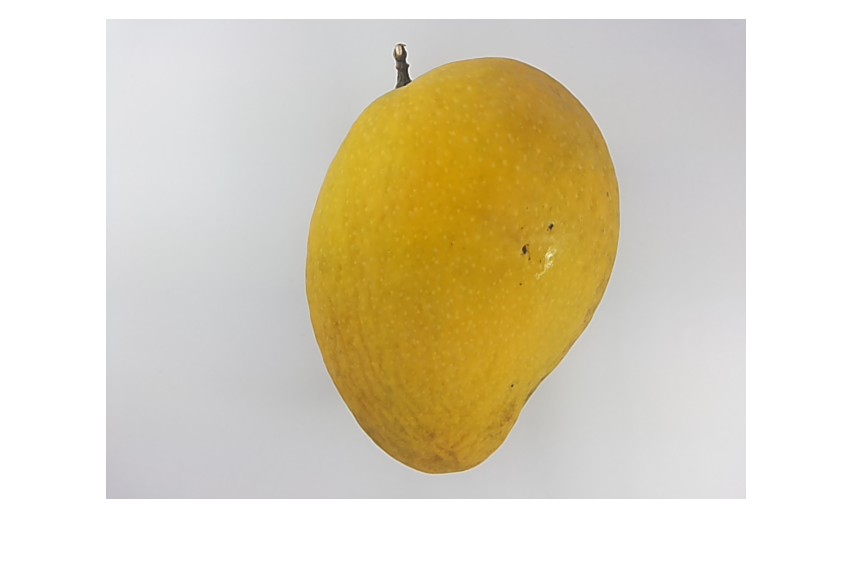

%Applying NCC to the ripe and unripe images
for i = 1:numImages_ripe
    imshow(ripe_images{i});
    [COLORS(i,2), COLORS(i,3), COLORS(i,4)] = NCCimage(ripe_images{i});
end

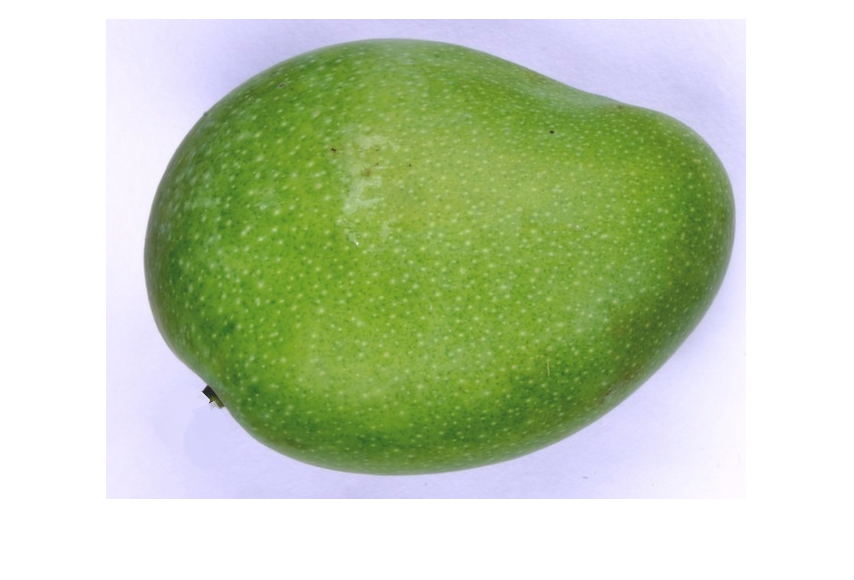


for i = 1:numImages_unripe
    imshow(unripe_images{i});
    [COLORS(i+numImages_ripe,2), COLORS(i+numImages_ripe,3), COLORS(i+numImages_ripe,4)] = NCCimage(unripe_images{i});
end

%setting up the testing part of the program
storage = zeros(numImages_ripe+numImages_unripe,1);
storage(1:numImages_ripe) = 1;
weight = rand(4,1) * 0.01 ;
learning_rate = 0.01; 
epochs = 700000; 
beta = 1;

A = zeros(numImages_ripe+numImages_unripe,1);
Z= zeros(numImages_ripe+numImages_unripe,1);

for epoch = 1:epochs

    for i = 1:numImages_ripe+numImages_unripe

        a = dot(COLORS(i,:), weight); 
        A(i) = a;
        z = sigmoid((beta*a)); %activation function
        Z(i) = z;
        %weight change
        delta_weight = learning_rate * (storage(i,:) - z) * COLORS(i,:)';
        %changing the weight
        weight = weight + delta_weight;
    end
end


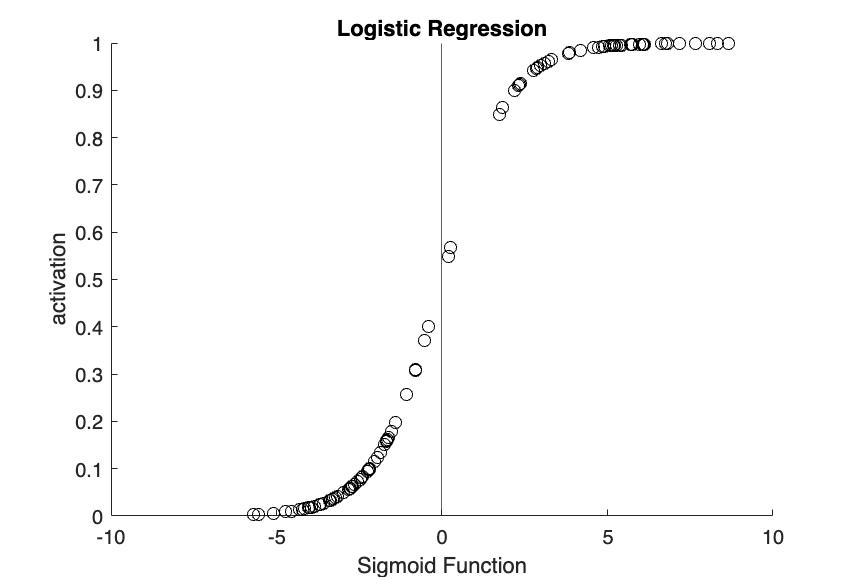

%Plotting
scatter(A(:,1), Z(:,1), 'k');
hold on; 
xlim([-10 10]);
xline(0, 'b');
title('Logistic Regression');
xlabel('Sigmoid Function');
ylabel('activation');
hold off;

### Testing

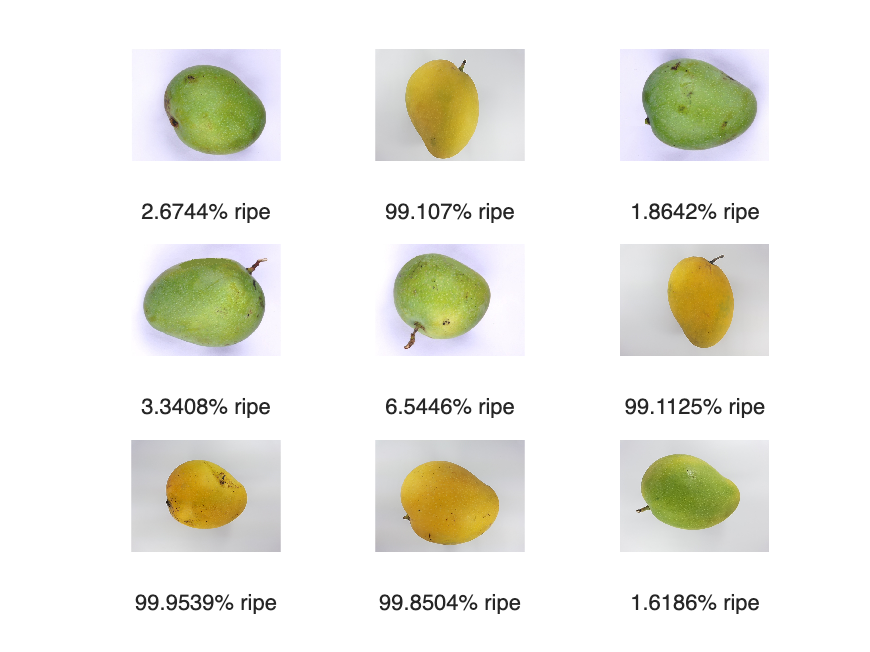

cd('~/Documents/MATLAB/mangoripeness/Test/');
fileList_test = dir('*.jpg'); 
numImages_test = numel(fileList_test);
test_images = cell(numImages_test, 1);

for i = 1:numImages_test
    test_images{i} = imread(fileList_test(i).name);
end

% Randomly select 9 indices to show 
selected_indices = randi(numImages_test, [1, 9]);

% Creating a subplot to display the images
figure;
for i = 1:9
    subplot(3, 3, i);
    index = selected_indices(i);
    LogisticRegression(test_images, index, weight, 1);
end

#### Functions used

function g = sigmoid(x) %activation function
    g = 1 / (1 + exp(-x)); 
end

function [nred, ngreen, nblue] = NCCimage(image)
    I = im2double(image);
    cropped = I(220:260, 220:260, :);
    [red, green, blue] = imsplit(cropped);
    [nred, ngreen,nblue] = NCC(red, green, blue);
    nred = mean2(nred);
    ngreen = mean2(ngreen);
    nblue = mean2(nblue);
end


function [r,g,b] = NCC(red, green, blue)
    I = red + green + blue;
    I(I==0) = 100000;
    r = red./I;
    g = green./I;
    b = blue./I;
end


function show = LogisticRegression(images, index, weight, beta)
    COLORS = zeros(1, 4); 
    COLORS(1, 1) = 1;
    I = images{index};
    show = imshow(I);
    [COLORS(1, 2), COLORS(1, 3), COLORS(1, 4)] = NCCimage(I);
    a = dot(COLORS, weight);
    p = sigmoid((beta * a));
    xlabel([num2str(p * 100) '% ripe']);
end

